Question 1.a - bisection method

func1 = @(x) sqrt(x) - cos(x)

func1 = function_handle with value:
    @(x)sqrt(x)-cos(x)



a1 = 0

a1 = 0

b1 = 1

b1 = 1


max_iter = 100

max_iter = 100

tol = 1e-5

tol = 1.0000e-05

plotting the func1

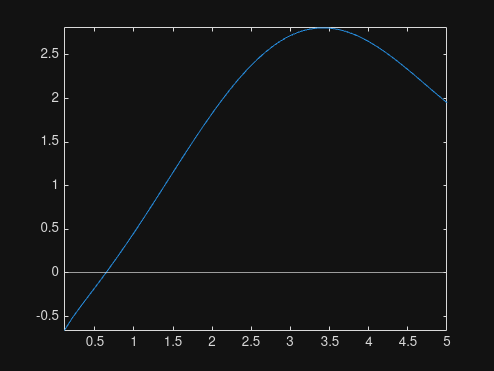

figure
fplot(func1)
yline(0)

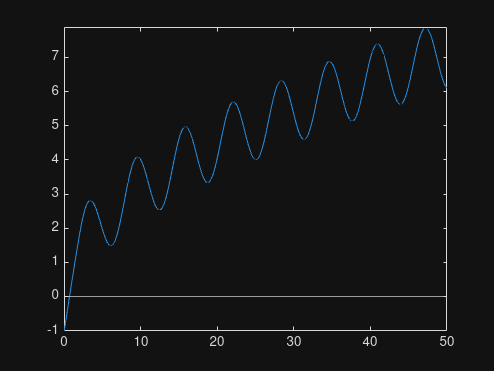

figure
fplot(func1, [0, 50])
yline(0)

[root1, iter1, tab1] = bisection_method_function(...
    a1, b1, tol, max_iter, func1 ...
)

root1 = 0.6417

iter1 = 16

tab1 = 16×7 table
    iter       a          b          p           f_a           f_b            f_p    
    ____    _______    _______    _______    ___________    __________    ___________

      1           0          1        0.5             -1        0.4597       -0.17048
      2         0.5          1       0.75       -0.17048        0.4597        0.13434
      3         0.5       0.75      0.625       -0.17048       0.13434      -0.020394
      4       0.625       0.75     0.6875      -0.020394       0.13434       0.056321
      5       0.625     0.6875    0.65625      -0.020394      0.056321       0.017807
      6       0.625    0.65625    0.64062      -0.020394      0.017807     -0.0013318
      7     0.64062    0.65625    0.64844     -0.001331

fprintf("Root: %.6f, Iterations: %d\n", root1, iter1)

Root: 0.641708, Iterations: 16


disp(tab1)

    iter       a          b          p           f_a           f_b            f_p    
    ____    _______    _______    _______    ___________    __________    ___________

      1           0          1        0.5             -1        0.4597       -0.17048
      2         0.5          1       0.75       -0.17048        0.4597        0.13434
      3         0.5       0.75      0.625       -0.17048       0.13434      -0.020394
      4       0.625       0.75     0.6875      -0.020394       0.13434       0.056321
      5       0.625     0.6875    0.65625      -0.020394      0.056321       0.017807
      6       0.625    0.65625    0.64062      -0.020394      0.017807     -0.0013318
      7     0.64062    0.65625    0.64844     -0.0013318      0.017807   

Question 1.b - bisection method

func2 = @(x) x.^4 - 2.*x.^3 - 4.*x.^2 + 4.*x + 4

func2 = function_handle with value:
    @(x)x.^4-2.*x.^3-4.*x.^2+4.*x+4



% intervals = {[-2, -1], [-1, 0], [1, 2], [2, 3]}
intervals = [-2, -1; -1, 0; 1, 2; 2, 3]

intervals =     -2    -1
    -1     0
     1     2
     2     3


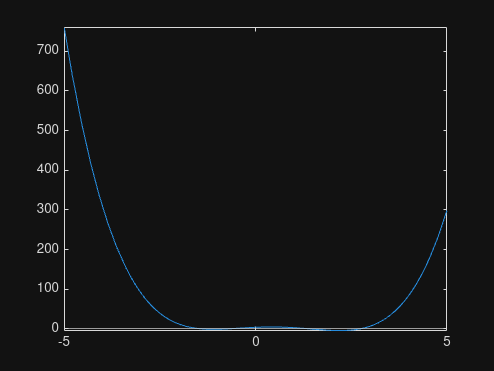

figure
fplot(func2)
yline(0)

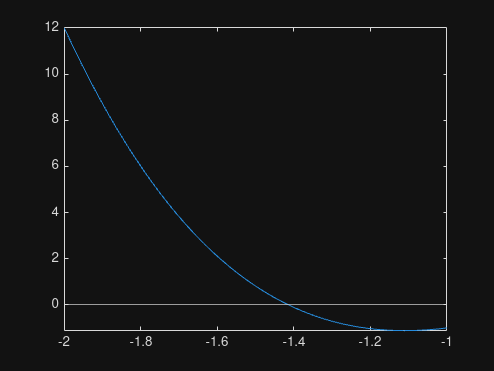

figure
fplot(func2, [-2, -1])
yline(0)

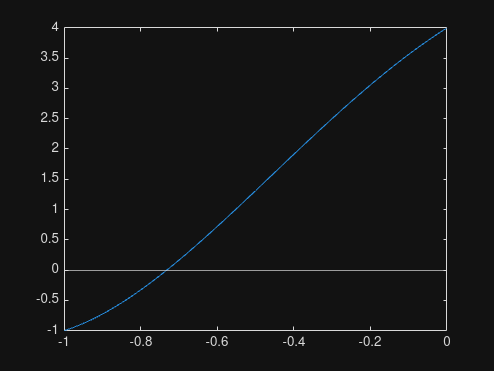

figure
fplot(func2, [-1, 0])
yline(0)

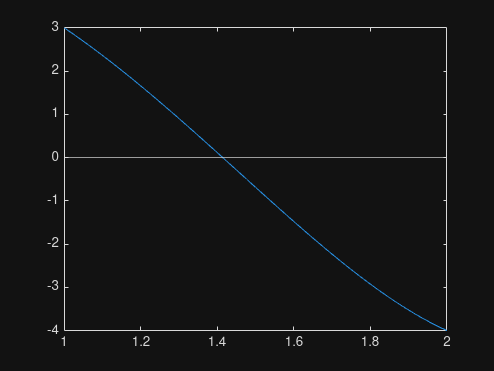

figure
fplot(func2, [1, 2])
yline(0)

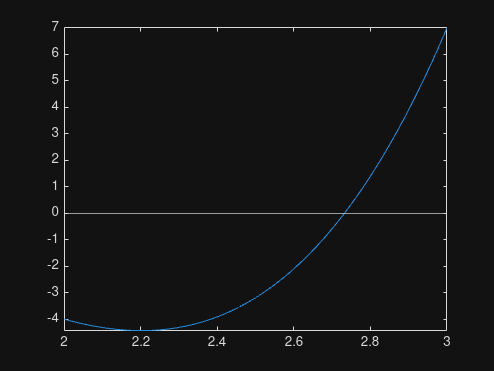

figure
fplot(func2, [2, 3])
yline(0)

% 4 roots

for interval = intervals'
    a = interval(1)
    b = interval(2)

    [root, iter, table] = bisection_method_function(...
        a, b, tol, max_iter, func2 ...
    )
    fprintf("Root: %.6f, Iterations: %d\n", root, iter)
    disp(table)
end

a = -2

b = -1

root = -1.4142

iter = 17

table = 17×7 table
    iter       a          b          p          f_a            f_b            f_p    
    ____    _______    _______    _______    __________    ___________    ___________

      1          -2         -1       -1.5            12             -1         0.8125
      2        -1.5         -1      -1.25        0.8125             -1       -0.90234
      3        -1.5      -1.25     -1.375        0.8125       -0.90234       -0.28882
      4        -1.5     -1.375    -1.4375        0.8125       -0.28882        0.19533
      5     -1.4375     -1.375    -1.4062       0.19533       -0.28882      -0.062667
      6     -1.4375    -1.4062    -1.4219       0.19533      -0.062667       0.062263
      7     -1.4219    -1.4062    -1.4141      0.06226

Root: -1.414207, Iterations: 17


    iter       a          b          p          f_a            f_b            f_p    
    ____    _______    _______    _______    __________    ___________    ___________

      1          -2         -1       -1.5            12             -1         0.8125
      2        -1.5         -1      -1.25        0.8125             -1       -0.90234
      3        -1.5      -1.25     -1.375        0.8125       -0.90234       -0.28882
      4        -1.5     -1.375    -1.4375        0.8125       -0.28882        0.19533
      5     -1.4375     -1.375    -1.4062       0.19533       -0.28882      -0.062667
      6     -1.4375    -1.4062    -1.4219       0.19533      -0.062667       0.062263
      7     -1.4219    -1.4062    -1.4141      0.062263      -0.062667   

a = -1

b = 0

root = -0.7320

iter = 17

table = 17×7 table
    iter       a           b           p            f_a           f_b            f_p    
    ____    ________    ________    ________    ___________    __________    ___________

      1           -1           0        -0.5             -1             4         1.3125
      2           -1        -0.5       -0.75             -1        1.3125      -0.089844
      3        -0.75        -0.5      -0.625      -0.089844        1.3125        0.57837
      4        -0.75      -0.625     -0.6875      -0.089844       0.57837        0.23268
      5        -0.75     -0.6875    -0.71875      -0.089844       0.23268       0.068086
      6        -0.75    -0.71875    -0.73438      -0.089844      0.068086      -0.011768
      7     -0.73438    -0.718

Root: -0.732048, Iterations: 17


    iter       a           b           p            f_a           f_b            f_p    
    ____    ________    ________    ________    ___________    __________    ___________

      1           -1           0        -0.5             -1             4         1.3125
      2           -1        -0.5       -0.75             -1        1.3125      -0.089844
      3        -0.75        -0.5      -0.625      -0.089844        1.3125        0.57837
      4        -0.75      -0.625     -0.6875      -0.089844       0.57837        0.23268
      5        -0.75     -0.6875    -0.71875      -0.089844       0.23268       0.068086
      6        -0.75    -0.71875    -0.73438      -0.089844      0.068086      -0.011768
      7     -0.73438    -0.71875    -0.72656     

a = 1

b = 2

root = 1.4142

iter = 17

table = 17×7 table
    iter      a         b         p          f_a            f_b            f_p    
    ____    ______    ______    ______    __________    ___________    ___________

      1          1         2       1.5             3             -4        -0.6875
      2          1       1.5      1.25             3        -0.6875         1.2852
      3       1.25       1.5     1.375        1.2852        -0.6875        0.31274
      4      1.375       1.5    1.4375       0.31274        -0.6875       -0.18651
      5      1.375    1.4375    1.4062       0.31274       -0.18651       0.063676
      6     1.4062    1.4375    1.4219      0.063676       -0.18651      -0.061318
      7     1.4062    1.4219    1.4141      0.063676      -0.061318      0.001

Root: 1.414207, Iterations: 17


    iter      a         b         p          f_a            f_b            f_p    
    ____    ______    ______    ______    __________    ___________    ___________

      1          1         2       1.5             3             -4        -0.6875
      2          1       1.5      1.25             3        -0.6875         1.2852
      3       1.25       1.5     1.375        1.2852        -0.6875        0.31274
      4      1.375       1.5    1.4375       0.31274        -0.6875       -0.18651
      5      1.375    1.4375    1.4062       0.31274       -0.18651       0.063676
      6     1.4062    1.4375    1.4219      0.063676       -0.18651      -0.061318
      7     1.4062    1.4219    1.4141      0.063676      -0.061318      0.0012085
      8     1.

a = 2

b = 3

root = 2.7320

iter = 17

table = 17×7 table
    iter      a         b         p          f_a           f_b            f_p    
    ____    ______    ______    ______    __________    __________    ___________

      1          2         3       2.5            -4             7        -3.1875
      2        2.5         3      2.75       -3.1875             7        0.34766
      3        2.5      2.75     2.625       -3.1875       0.34766        -1.7576
      4      2.625      2.75    2.6875       -1.7576       0.34766       -0.79564
      5     2.6875      2.75    2.7188      -0.79564       0.34766       -0.24747
      6     2.7188      2.75    2.7344      -0.24747       0.34766       0.044125
      7     2.7188    2.7344    2.7266      -0.24747      0.044125       -0.10315
    

Root: 2.732048, Iterations: 17


    iter      a         b         p           f_a           f_b            f_p    
    ____    ______    ______    ______    ___________    __________    ___________

      1          2         3       2.5             -4             7        -3.1875
      2        2.5         3      2.75        -3.1875             7        0.34766
      3        2.5      2.75     2.625        -3.1875       0.34766        -1.7576
      4      2.625      2.75    2.6875        -1.7576       0.34766       -0.79564
      5     2.6875      2.75    2.7188       -0.79564       0.34766       -0.24747
      6     2.7188      2.75    2.7344       -0.24747       0.34766       0.044125
      7     2.7188    2.7344    2.7266       -0.24747      0.044125       -0.10315
      8     2.

Question 3.a - newton's method

func3 = @(x) x.^3 + 3.*x.^2 - 1

func3 = function_handle with value:
    @(x)x.^3+3.*x.^2-1



p0_vect = [-2.5, -0.5, 0.5]

p0_vect =    -2.5000   -0.5000    0.5000


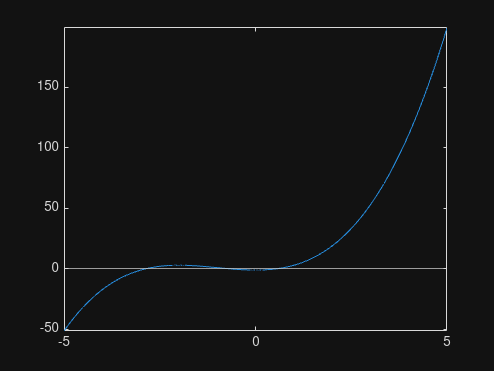

figure
fplot(func3)
yline(0)

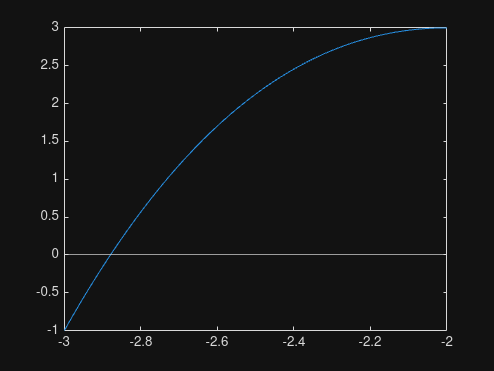

figure
fplot(func3, [-3, -2])
yline(0)

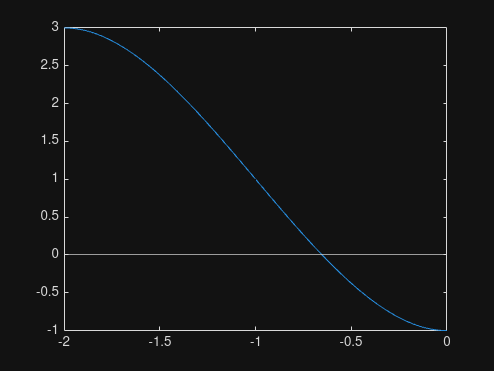

figure
fplot(func3, [-2, 0])
yline(0)

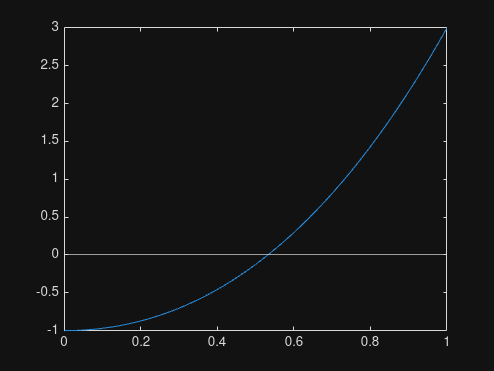

figure
fplot(func3, [0, 1])
yline(0) % 3 roots

for p0 = p0_vect
    [root, iter, table] = newton_method_function(...
        p0, tol, max_iter, func3...
    )
    fprintf("Root: %.6f, Iterations: %d\n", root, iter)
    disp(table)
end

root = -2.8794

iter = 5

table = 5×6 table
    iter      p0          p          f_p0        df_p0         f_p    
    ____    _______    _______    ___________    ______    ___________

     1         -2.5    -3.0667          2.125      3.75         -1.627
     2      -3.0667    -2.9009         -1.627    9.8133       -0.16586
     3      -2.9009    -2.8797       -0.16586      7.84     -0.0025428
     4      -2.8797    -2.8794     -0.0025428       7.6    -6.3123e-07
     5      -2.8794    -2.8794    -6.3123e-07    7.5963     -3.908e-14

	Get insights using Copilot


Root: -2.879385, Iterations: 5


    iter      p0          p          f_p0        df_p0         f_p    
    ____    _______    _______    ___________    ______    ___________

     1         -2.5    -3.0667          2.125      3.75         -1.627
     2      -3.0667    -2.9009         -1.627    9.8133       -0.16586
     3      -2.9009    -2.8797       -0.16586      7.84     -0.0025428
     4      -2.8797    -2.8794     -0.0025428       7.6    -6.3123e-07
     5      -2.8794    -2.8794    -6.3123e-07    7.5963     -3.908e-14



root = -0.6527

iter = 4

table = 4×6 table
    iter       p0          p           f_p0        df_p0         f_p    
    ____    ________    ________    __________    _______    ___________

     1          -0.5    -0.66667        -0.375      -2.25       0.037037
     2      -0.66667    -0.65278      0.037037    -2.6667     0.00019558
     3      -0.65278     -0.6527    0.00019558    -2.6383     5.7248e-09
     4       -0.6527     -0.6527    5.7248e-09    -2.6382    -1.1102e-16

	Get insights using Copilot


Root: -0.652704, Iterations: 4


    iter       p0          p           f_p0        df_p0         f_p    
    ____    ________    ________    __________    _______    ___________

     1          -0.5    -0.66667        -0.375      -2.25       0.037037
     2      -0.66667    -0.65278      0.037037    -2.6667     0.00019558
     3      -0.65278     -0.6527    0.00019558    -2.6383     5.7248e-09
     4       -0.6527     -0.6527    5.7248e-09    -2.6382    -1.1102e-16



root = 0.5321

iter = 3

table = 3×6 table
    iter      p0          p          f_p0       df_p0        f_p    
    ____    _______    _______    __________    ______    __________

     1          0.5    0.53333        -0.125      3.75      0.005037
     2      0.53333    0.53209      0.005037    4.0533    7.1018e-06
     3      0.53209    0.53209    7.1018e-06    4.0419     1.419e-11

	Get insights using Copilot


Root: 0.532089, Iterations: 3


    iter      p0          p          f_p0       df_p0        f_p    
    ____    _______    _______    __________    ______    __________

     1          0.5    0.53333        -0.125      3.75      0.005037
     2      0.53333    0.53209      0.005037    4.0533    7.1018e-06
     3      0.53209    0.53209    7.1018e-06    4.0419     1.419e-11



Question 3.b - newton's method

func4 = @(x) exp(-x) - sin(x)

func4 = function_handle with value:
    @(x)exp(-x)-sin(x)



p0 = 0.25

p0 = 0.2500

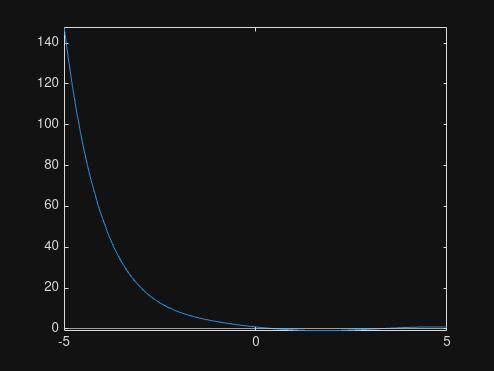

figure
fplot(func4)
yline(0)

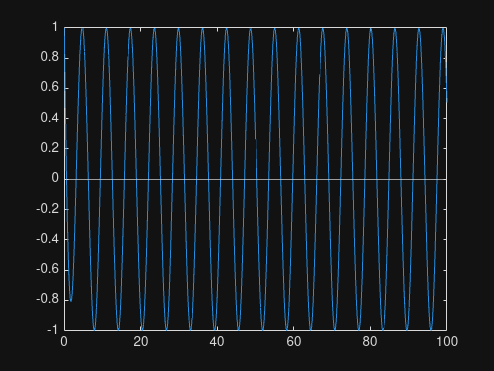

figure
fplot(func4, [0, 100])
yline(0)
ylim([-1, 1])

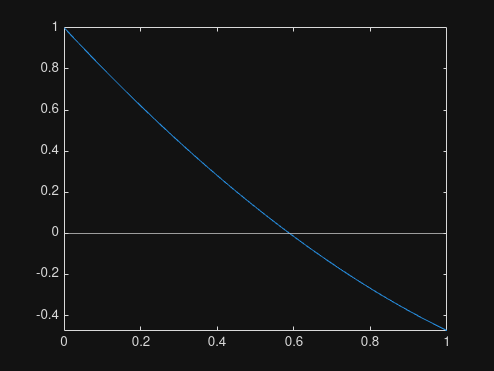

figure
fplot(func4, [0, 1])
yline(0)

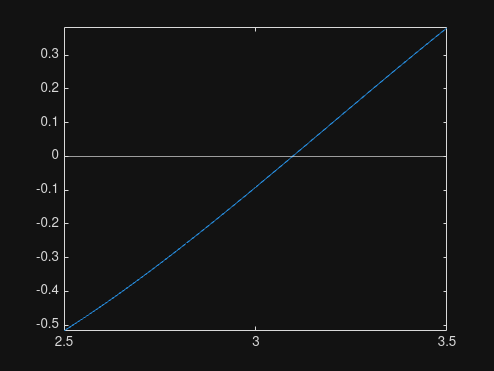

figure
fplot(func4, [2.5, 3.5])
yline(0)

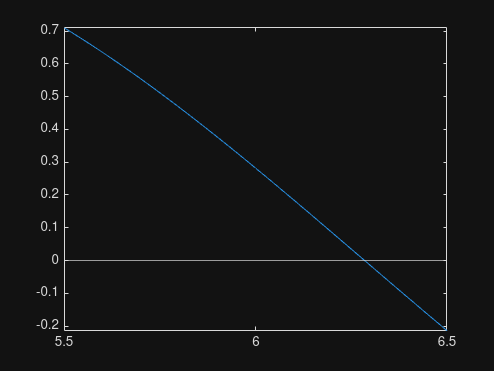

figure
fplot(func4, [5.5, 6.5])
yline(0)

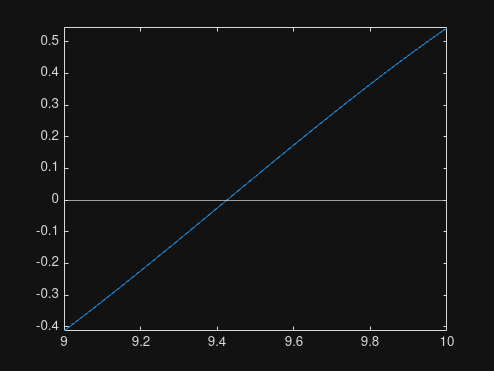

figure
fplot(func4, [9, 10])
yline(0) % infinite roots

[root4, iter4, table4] = newton_method_function(...
    p0, tol, max_iter, func4...
    )

root4 = 0.5885

iter4 = 4

table4 = 4×6 table
    iter      p0          p          f_p0        df_p0        f_p    
    ____    _______    _______    __________    _______    __________

     1         0.25    0.55405        0.5314    -1.7477      0.048478
     2      0.55405    0.58807      0.048478     -1.425    0.00063878
     3      0.58807    0.58853    0.00063878    -1.3874    1.1767e-07
     4      0.58853    0.58853    1.1767e-07    -1.3869    3.9968e-15

	Get insights using Copilot


fprintf("Root: %.6f, Iterations: %d\n", root4, iter4)

Root: 0.588533, Iterations: 4


disp(table4)

    iter      p0          p          f_p0        df_p0        f_p    
    ____    _______    _______    __________    _______    __________

     1         0.25    0.55405        0.5314    -1.7477      0.048478
     2      0.55405    0.58807      0.048478     -1.425    0.00063878
     3      0.58807    0.58853    0.00063878    -1.3874    1.1767e-07
     4      0.58853    0.58853    1.1767e-07    -1.3869    3.9968e-15

